addpath("c:/git/UQ4PDE_Homeworks/Homework 2/sobol package/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 2/functions/")

cutoff_fourier = [29 21 19 16];
nu = [0.5, 1.5, 2.5, 0];
titles = {'0.5','1.5','2.5', 'inf'};
c_alpha = 3;

`Homework 2, Part 2, Task 2:`

`Generalized control variates using QMC`

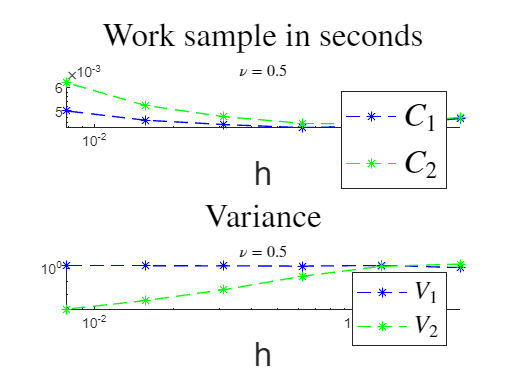

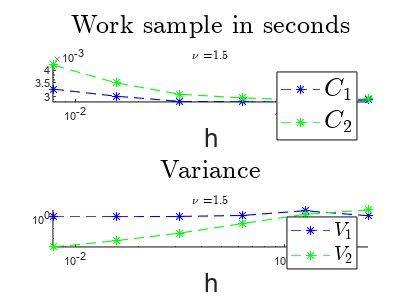

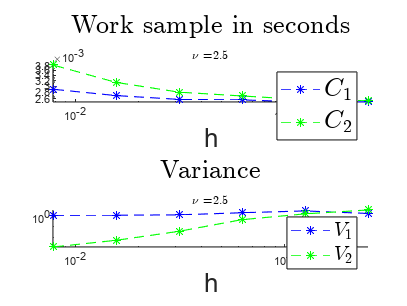

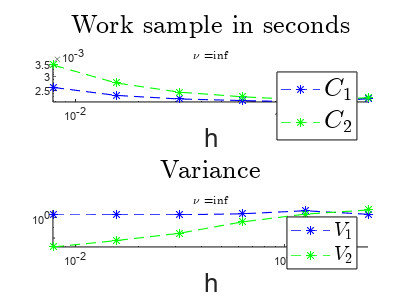

I = [2^2,2^3,2^4,2^5,2^6,2^7];
h = 1./I;
M = [500,500,500,500];
N = 100;
Var_1 = zeros(length(nu),length(I));
Var_2 = zeros(length(nu),length(I));

for j = 1:length(nu)
    C_1 = zeros(N,length(I));
    C_2 = zeros(N,length(I));
    for n = 1:N
        for i = 1:length(I)
            tC1 = tic;
            y = GenerateSamples(cutoff_fourier(1),1);
            z = GenerateSamples(cutoff_fourier(1),1);
            fourier = fourierkoeff(nu(j),cutoff_fourier(j));
            CalculateQoI( I(i), h(i),fourier,cutoff_fourier(j),y,z);
            C_1(n,i) = toc(tC1);

            tC2 = tic;
            CalculateQoI( 2*I(i), h(i)/2,fourier,cutoff_fourier(j),y,z);
            C_2(n,i) = toc(tC2) + C_1(n,i);
        end
    end
    figure
    subplot(2,1,1)
    hold on
    set(gca, 'XScale', 'log', 'YScale', 'log')
    plot(h,mean(C_1),'*--b')
    plot(h,mean(C_2),'*--g')
    hold off

    title('Work sample in seconds',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')
    xlabel('h','FontSize',20)
    legend('$C_1$','$C_2$','interpreter','latex','FontSize',20)


    MCRes=zeros(2,length(I));
    QDiff=zeros(1,length(I));

    y = GenerateSamples(cutoff_fourier(1),M(j));
    z = GenerateSamples(cutoff_fourier(1),M(j));
    for i = 1:length(I)
        V1 = zeros(1,M(j));
        V2 = zeros(1,M(j));
        V3 = zeros(1,M(j));
        V4 = zeros(1,M(j));
        for m=1:M(j)
            V1(m) = CalculateQoI( I(i), h(i),fourier,cutoff_fourier(j),y(:,m),z(:,m));
            V2(m) = CalculateQoI( 2*I(i), h(i)/2,fourier,cutoff_fourier(j),y(:,m),z(:,m));

            MCRes(1,i)=MCRes(1,i)+V1(m);
            MCRes(2,i)=MCRes(2,i)+V1(m) - V2(m);
        end
        MCRes(:,i)=MCRes(:,i)./M(j);
        Var=0;
        Var_diff = 0;
        for m=1:M(j)
            Var=Var+( V1(m) -MCRes(1,i) )^2;
            Var_diff=Var_diff+( V1(m) - V2(m) -MCRes(2,i))^2;
        end
        Var_1(j,i)=Var./(M(j)-1);
        Var_2(j,i)=Var_diff./(M(j)-1);
    end

    subplot(2,1,2)
    hold on
    set(gca, 'YScale', 'log', 'XScale', 'log')
    plot(h,Var_1(j,:),'*--b')
    plot(h,Var_2(j,:),'*--g')
    hold off
    
    title('Variance',['$\nu = $' , titles{j}],'FontSize',20,'interpreter','latex')
    xlabel('h','FontSize',20)
    legend('$V_1$','$V_2$','interpreter','latex','FontSize',15)
end

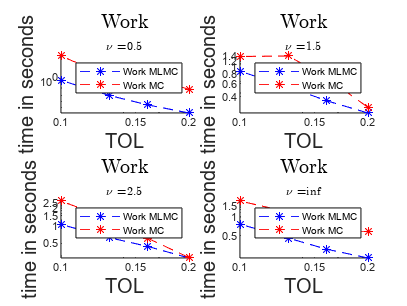

j = 1

MLMCres = -1.5976

MLMCvar = 0.0018

M_1 = 732

M_2 = 48

MLMCres = -1.6539

MLMCvar = 0.0012

M_1 = 1143

M_2 = 75

MLMCres = -1.6510

MLMCvar = 9.8405e-04

M_1 = 1732

M_2 = 113

MLMCres = -1.6265

MLMCvar = 5.6970e-04

M_1 = 2927

M_2 = 191

j = 2

MLMCres = -1.7361

MLMCvar = 0.0044

M_1 = 911

M_2 = 240

MLMCres = -1.6804

MLMCvar = 0.0026

M_1 = 1424

M_2 = 375

MLMCres = -1.5600

MLMCvar = 0.0017

M_1 = 2157

M_2 = 569

MLMCres = -1.5801

MLMCvar = 0.0011

M_1 = 3645

M_2 = 961

j = 3

MLMCres = -1.6167

MLMCvar = 0.0030

M_1 = 1081

M_2 = 357

MLMCres = -1.5874

MLMCvar = 0.0018

M_1 = 1688

M_2 = 558

MLMCres = -1.6220

MLMCvar = 0.0013

M_1 = 2558

M_2 = 845

MLMCres = -1.6219

MLMCvar = 7.2613e-04

M_1 = 4322

M_2 = 1428

j = 4

MLMCres = -1.6271

MLMCvar = 0.0027

M_1 = 888

M_2 = 58

MLMCres = -1.5629

MLMCvar = 0.0013

M_1 = 1387

M_2 = 91

MLMCres = -1.5882

MLMCvar = 9.6517e-04

M_1 = 2101

M_2 = 137

MLMCres = -1.6063

MLMCvar = 6.4953e-04

M_1 = 3550

M_2 = 232


TOL = [0.2,0.16,0.13,0.1];
I0=4;
h0=1/I0;
M_0 = 80;
work_MLMC = zeros(length(nu),length(TOL));
work_QMC = zeros(length(nu),length(TOL));
figure
for j = 1:length(nu)
    j
    for i = 1:length(TOL)
        tMLMC = tic;
        [MLMCres, MLMCvar, M_1, M_2] = MLMC(TOL(i), h_MC(j), h, Var_1(j,:), C_1, Var_2(j,:), C_2, nu(j),cutoff_fourier(j))
        work_MLMC(j,i) = toc(tMLMC);

        tQMC = tic;
        [~,~,~,~,~,~,~,~] = AdaptiveMC(M0, p(j), c_alpha, TOL(i), I0, h0, nu(j),cutoff_fourier(j));
        work_QMC(j,i) = toc(tQMC);
    end
    subplot(2,2,j)
    hold on
    plot(TOL,work_MLMC(j,:),'*--b')
    plot(TOL,work_QMC(j,:),'*--r')
    hold off
    set(gca, 'YScale', 'log', 'XScale', 'log')
    title('Work',['$\nu = $' , titles{j}],'FontSize',15,'interpreter','latex')
    xlabel('TOL','FontSize',15)
    ylabel('time in seconds','FontSize',15)
    legend('Work MLMC','Work MC')      
end

work_QMC

work_QMC =     0.6613    1.1313    1.1372    2.7484
    0.2895    0.7185    1.4065    1.3848
    0.2823    0.6078    1.2931    2.6692
    0.5895    0.5893    1.1957    1.8101


work_MLMC

work_MLMC =     0.2409    0.3400    0.5089    0.9724
    0.2436    0.3546    0.5423    0.8793
    0.2774    0.4390    0.6214    1.0516
    0.2183    0.3020    0.4561    0.7663
